## Roots of Equations

### Bracketing Method

#### Bisection Method

clear
clc

x_l = 0.1;
x_u = 2;

x_r = (x_l + x_u)/2;

epsilon_a = 1E-10;

#### False Position Method

#### 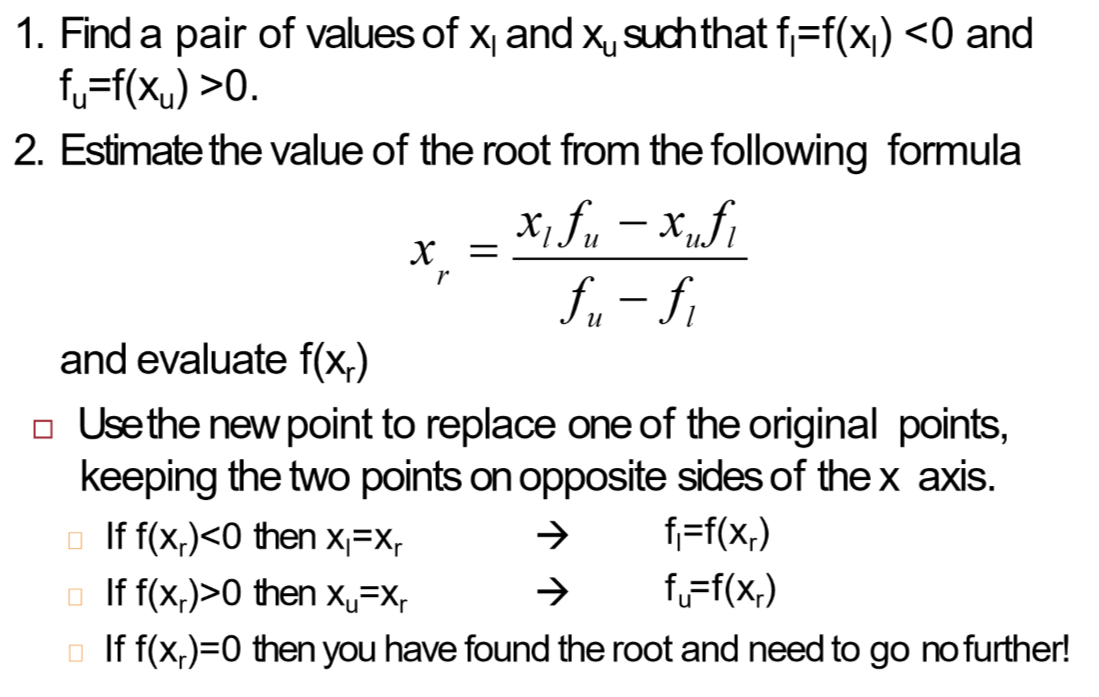

clear
clc

### Example 1

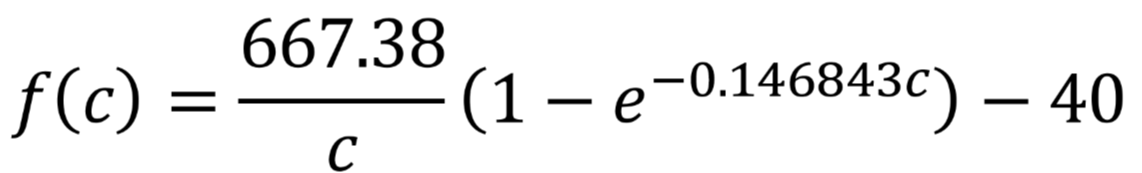

syms f c;
f(c) = (667.38/c)*(1 - exp(-0.146843*c))-40;
plot(1:20,f(1:20));grid on;
x_l = 4;
x_u = 20;

for i=1:10
    f_xl = f(x_l);
    f_xu = f(x_u);
    
    x_r = (x_l*f_xu - x_u*f_xl)/(f_xu - f_xl);
    
    f_xr = f(x_r);
    
    if f_xr < 0
        x_u = x_r;
        fprintf("xl");
    elseif f_xr > 0
        x_l = x_r;
        fprintf("xr");
    end
    
    fprintf('%f %f %f %f \n', f_xl, f_xu, x_r, f_xr);
end